# Solving XOR problem with a multilayer perceptron

The exercise demonstrates an application of a multilayer perceptron for solving the XOR problem. XOR or "exclusive or" problem is a classical problem in neural networks research that consists of solving a nonlinear "exclusive or" classification of 4 clusters of data into 2 output classes (class A and class B). 

Four clusters of data (A1, A1, B1, B2) are defined in 2-dimensional input space. (A,C) and (B,D) clusters represent XOR classification problem. 

The task is to define a neural network (multilayer perceptron) for solving the XOR problem..

2022 © Primož Potočnik ([University of Ljubljana](https://www.uni-lj.si), [Faculty of Mechanical Engineering](https://www.fs.uni-lj.si))

## Define 4 clusters of input data

close all, clear all, clc, format compact

Define the number of samples to train the neural network classifier and the offset between the clusters of data. Training is easier with a large offset (> 0.6) and more difficult with a smaller offset (0.5 - 0.6) due to the close boundaries between the classes. A very small offset (< 0.5) defines overlapping classes and a difficult classification problem that still can be solved by a neural network.

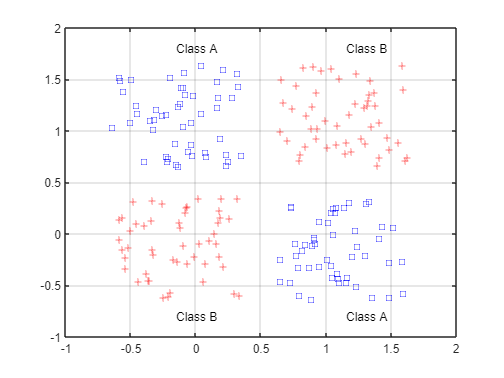

Nclass =50; % number of samples of each cluster
offset =0.65; % offset between classes

% define clusters of data
A1 = [rand(1,Nclass)-offset; rand(1,Nclass)+offset];
A2 = [rand(1,Nclass)+offset; rand(1,Nclass)-offset];
B1 = [rand(1,Nclass)+offset; rand(1,Nclass)+offset];
B2 = [rand(1,Nclass)-offset; rand(1,Nclass)-offset];

% plot data
plot(A1(1,:),A1(2,:),'bs')
hold on
grid on
plot(A2(1,:),A2(2,:),'bs')
plot(B1(1,:),B1(2,:),'r+')
plot(B2(1,:),B2(2,:),'r+')
% text labels for classes 
text(.5-offset,.5+2*offset,'Class A')
text(.5+offset,.5-2*offset,'Class A')
text(.5+offset,.5+2*offset,'Class B')
text(.5-offset,.5-2*offset,'Class B')

Plot data (4 clusters belonging to 2 classes)

## Prepare inputs & outputs for network training

Data from different clusters are collected into two classes of inputs. Outputs are properly encoded using two binary outputs.

% define inputs (combine samples from all four classes)
P = [A1 B1 A2 B2];

% define output coding for XOR problem, encode classes A and B
A = -1;
B =  1;

% define targets
T = [repmat(A,1,length(A1)) repmat(B,1,length(B1)) ...
     repmat(A,1,length(A2)) repmat(B,1,length(B2)) ];

## Create and train a multilayer perceptron

Built-in MATLAB function 'feedforwardnet' is used to construct the multilayer perceptron.

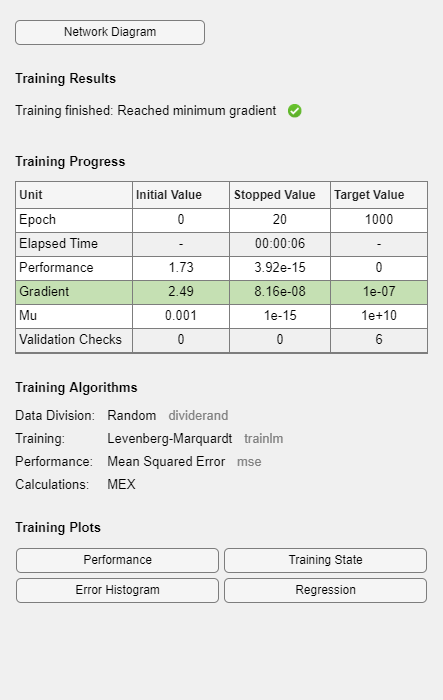

num_first_hidden_layer =7; % number of neurons in the first hidden layer
num_second_hidden_layer =5; % number of neurons in the first hidden layer

% create a neural network
net = feedforwardnet([num_first_hidden_layer num_second_hidden_layer]);

% training parameters
net.divideParam.trainRatio = 0.7; % training set [%]
net.divideParam.valRatio   = 0.15; % validation set [%]
net.divideParam.testRatio  = 0.15; % test set [%]

% train a neural network
[net,tr,Y,E] = train(net,P,T);

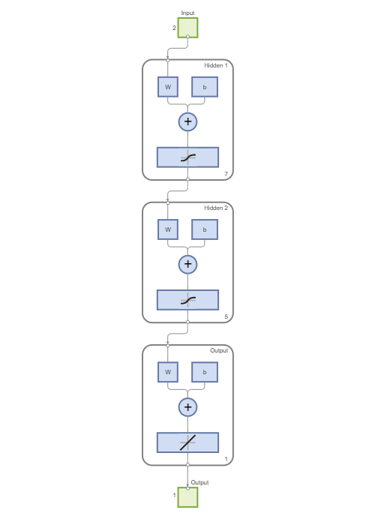

% show network
view(net)

## Evaluate network performance

Evaluate network performance by calculating the classification accuracy. 


$$\textrm{classification}\;\textrm{accuracy}=\frac{\textrm{number}\;\textrm{of}\;\textrm{correct}\;\textrm{predictions}}{\textrm{total}\;\textrm{number}\;\textrm{of}\;\textrm{predictions}}$$


% digitize network response
threshold = 0;
P = Y;
P(Y <  threshold) = A;
P(Y >= threshold) = B;

% calculate classification accuracy
classification_accuracy = length(find(P==T))/length(T)

classification_accuracy = 1

## Plot targets and network response to see how good the network learns the data

Compare the targets (blue) with the network response (red). Ideally, they should be equal (or at least very similar). 

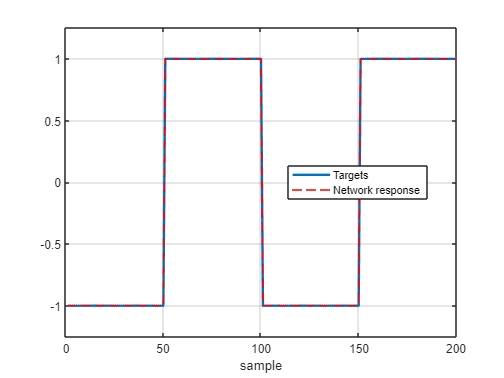

figure
plot(T','linewidth',2)
hold on
plot(Y','r--')
grid on
legend('Targets','Network response','location','best')
ylim([-1.25 1.25])
xlabel('sample')

## Plot classification result for the complete input space

The decision boundaries, representing how the trained network classifies the input data, are shown in two colors (cyan and magenta).

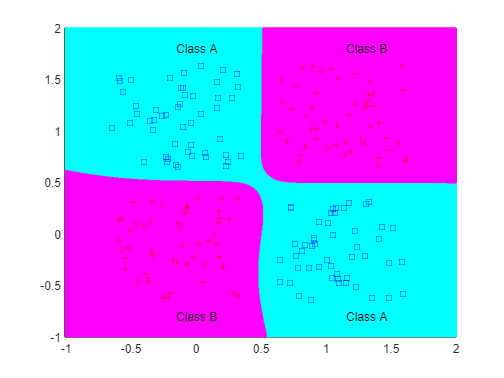

% generate a grid
span = -1:.005:2;
[P1,P2] = meshgrid(span,span);
input_grid = [P1(:) P2(:)]';

% simulate neural network on a grid
output_grid = net(input_grid);

% digitize network response
P = output_grid;
P(find(P <  threshold)) = A;
P(find(P >= threshold)) = B;

% plot classification regions
figure(1)
mesh(P1,P2,reshape(P,length(span),length(span))-5);
colormap cool
view(2)

% close all windows
close all force

## Suggestions

Try to expand the range of neural network parameters and see how the resulting network performs. 

Suggestions to experiment:

- Remove the second hidden layer (num_second_hidden_layer = [ ];) and see the result.

- Experiment with various selections of training parameters, e.g. [0.7 0.15 0.15], [1 0 0], [0.4 0.3 0.3]

- Try different training algorithms, such as: `'trainlm',` `'traingd', 'traincgb', ...` (see the [Documentation on 'feedforwardnet'](https://www.mathworks.com/help/deeplearning/ref/feedforwardnet.html))

Learn that a succesful application of a neural network requires fine-tuning of many design parameters.

## PowerPoint presentation

[NN4a_Backpropagation.pptx](matlab:open('./NN4a_Backpropagation.pptx'))